**List of image filenames**

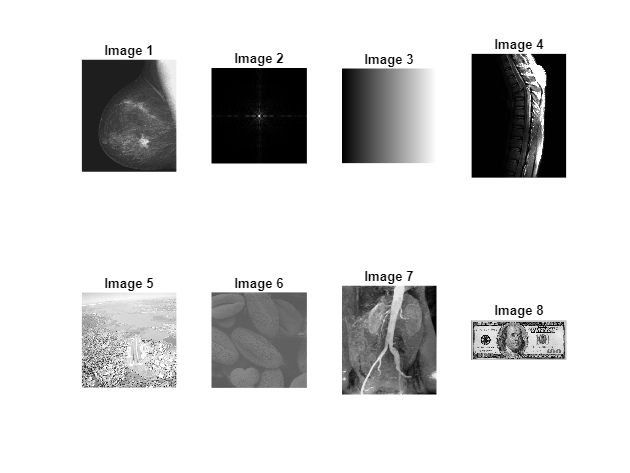

image_files = { 'Fig0304(a)(breast_digital_Xray).tif', ...
                'Fig0305(a)(DFT_no_log).tif', ...
                'Fig0307(a)(intensity_ramp).tif', ...
                'Fig0308(a)(fractured_spine).tif', ...
                'Fig0309(a)(washed_out_aerial_image).tif', ...
                'Fig0310(b)(washed_out_pollen_image).tif', ...
                'Fig0312(a)(kidney).tif', ...
                'Fig0314(a)(100-dollars).tif' };

output_folder = 'processed_images';

if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end


figure('Name', 'Original Images (2x4 Grid)', 'NumberTitle', 'off');

for i = 1:length(image_files)
    img = imread(image_files{i});
    
    % Convert to grayscale if RGB
    if size(img, 3) == 3
        img = rgb2gray(img);
    end

    % Display image in 2x4 grid
    subplot(2, 4, i);
    imshow(img);
    title(['Image ' num2str(i)]);
end

**Image Negative**

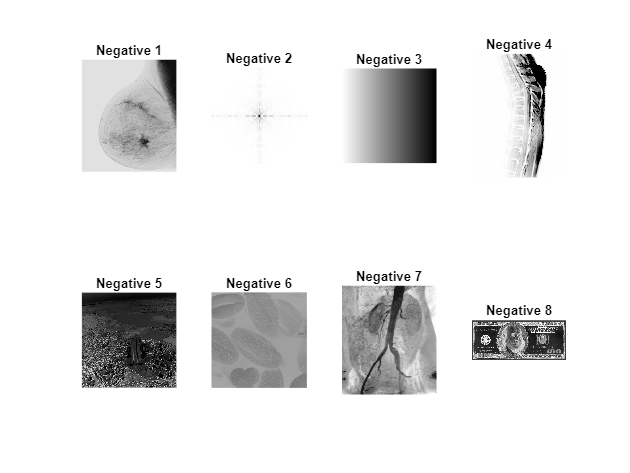

figure('Name', 'Image Negative', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img_negative = 255 - img;

    imwrite(img_negative, fullfile(output_folder, ['negative_' image_files{i}]));

    subplot(2,4,i); imshow(img_negative);
    title(['Negative ' num2str(i)]);
end

**Thresholding**

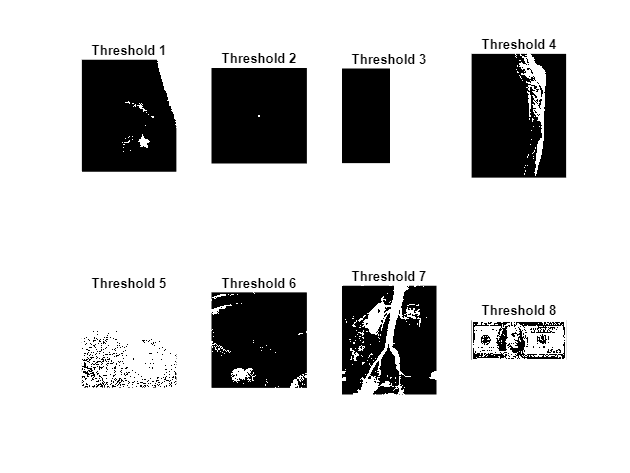

threshold = 128;
figure('Name', 'Thresholding', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img_threshold = img > threshold;

    imwrite(img_threshold * 255, fullfile(output_folder, ['threshold_' image_files{i}]));

    subplot(2,4,i); imshow(img_threshold);
    title(['Threshold ' num2str(i)]);
end

**Contrast Stretching**

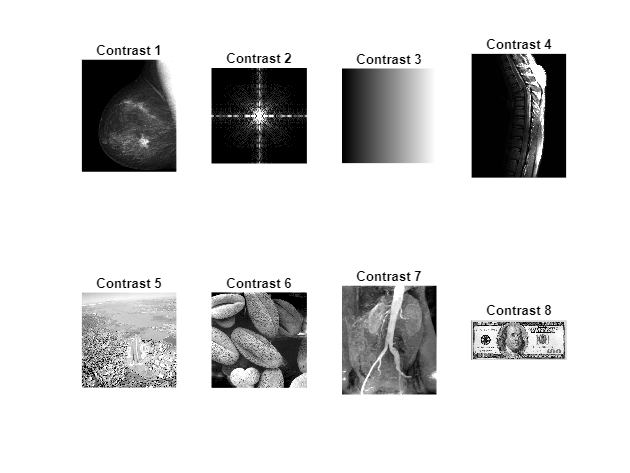

figure('Name', 'Contrast Stretching', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img_stretched = imadjust(img, stretchlim(img), [0 1]);

    imwrite(img_stretched, fullfile(output_folder, ['contrast_' image_files{i}]));

    subplot(2,4,i); imshow(img_stretched);
    title(['Contrast ' num2str(i)]);
end

**Gray Level Slicing**

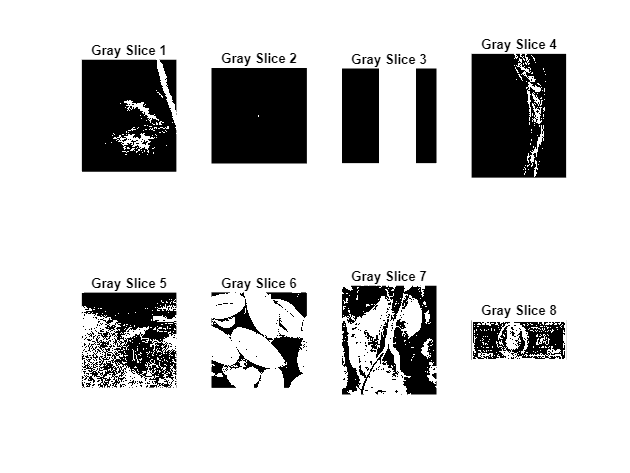

low = 100; high = 200;
figure('Name', 'Gray Level Slicing', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img_gray_slice = (img >= low & img <= high) * 255;

    imwrite(img_gray_slice, fullfile(output_folder, ['gray_slice_' image_files{i}]));

    subplot(2,4,i); imshow(img_gray_slice);
    title(['Gray Slice ' num2str(i)]);
end

**Power Law Transformation**

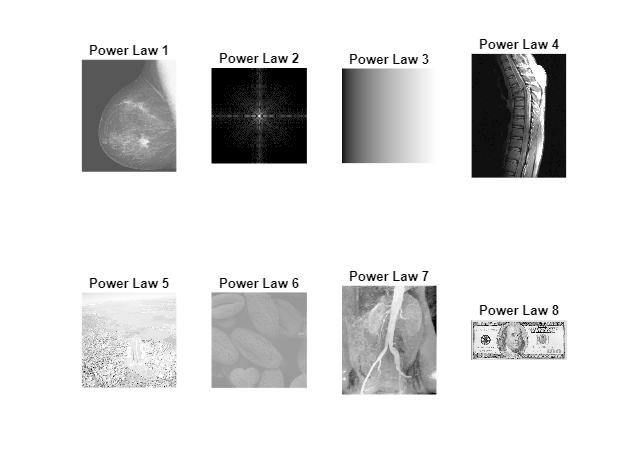

gamma = 0.5;
figure('Name', 'Power Law Transformation', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img_power = im2double(img) .^ gamma;
    img_power = uint8(255 * img_power);

    imwrite(img_power, fullfile(output_folder, ['power_' image_files{i}]));

    subplot(2,4,i); imshow(img_power);
    title(['Power Law ' num2str(i)]);
end

**Bit-Plane Slicing**

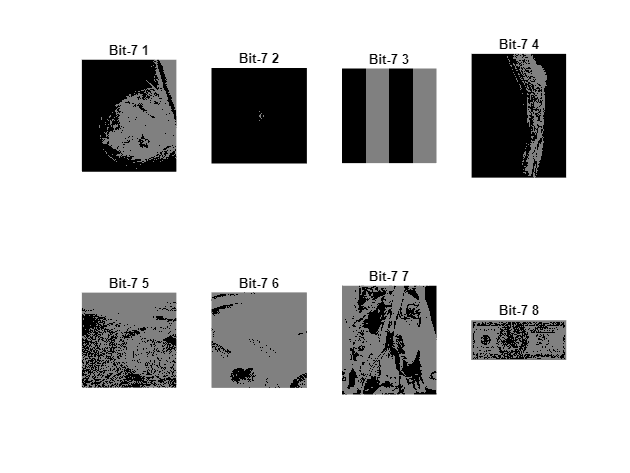

figure('Name', 'Bit-Plane Slicing - Bit 7', 'NumberTitle', 'off');
for i = 1:length(image_files)
    img = imread(image_files{i});
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    bit7 = bitget(img, 7) * 128;

    imwrite(bit7, fullfile(output_folder, ['bit7_' image_files{i}]));

    subplot(2,4,i); imshow(bit7);
    title(['Bit-7 ' num2str(i)]);
end